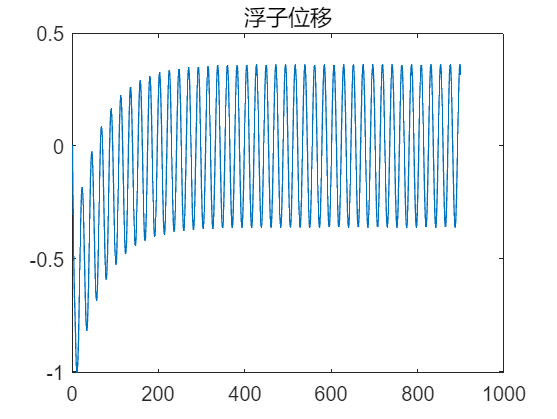

clc,clear
%initialize parameter
L=2.3-2/15;                 %重心距底端距离
ke=80000;                   %弹簧刚度 (N/m)
g=9.8;                      %重力加速度 (m/s2)
l0=0.5;                     %弹簧原长 (m)
rho=1025;                   %海水的密度 (kg/m3)
m1=4866;                    %浮子质量 (kg)
m2=2433;                    %振子质量 (kg)
w=1.4005;                   %入射波浪频率 (rad/s)orsay %入射波浪角速度（rad/s）                
dt=0.2;                     %步长设为0.2s
T=2*pi/w;                   %波浪周期（s)   
T_end=40*T;                 %总数值模拟时间(s)        
iter_times=ceil(T_end/dt);  %总迭代次数 
%%初值设置
V0=(m1+m2)/rho;             %初始沉入水中体积(m3)
l=l0-m2*g/ke;            %弹簧的初始长度 (m)
v1=0;                    %浮子的初始速度 (m/s)
v2=0;                    %振子的初始速度 (m/s)
x_f=0;                   %浮子的初始位移 (m) (以浮子的重心为坐标轴原点)
x_v=-(L-0.8-l);          %振子的初始位移 (m)
h=2.8-L;                 %水面的高度(m)
X=zeros(4,iter_times);
X(:,1)=[x_f;x_v;v1;v2];
flag=input('第一种情况请输入0,第二种情况输入1:');                %ture 表示第二种情况
if flag
    k=zeros(iter_times,1);
    for i=1:iter_times+1
        t=(i-1)*dt;
        K1=S_diff_equ(X(:,i),t,k(i),flag);
        K2=S_diff_equ(X(:,i)+K1*dt/2,t+dt/2,k(i),flag);
        K3=S_diff_equ((X(:,i)+K2*dt/2),t+dt/2,k(i),flag);
        K4=S_diff_equ((X(:,i)+K3*dt),t+dt,k(i),flag);
        X(:,i+1)=X(:,i)+dt/6*(K1+2*K2+2*K3+K4);
        k(i+1)=10000*sqrt(abs(X(3,i+1)-X(4,i+1)));
    end
else
    k=10000;
    for i=1:iter_times+1
        t=(i-1)*dt;
        K1=S_diff_equ(X(:,i),t,k,flag);
        K2=S_diff_equ(X(:,i)+K1*dt/2,t+dt/2,k,flag);
        K3=S_diff_equ((X(:,i)+K2*dt/2),t+dt/2,k,flag);
        K4=S_diff_equ((X(:,i)+K3*dt),t+dt,k,flag);
        X(:,i+1)=X(:,i)+dt/6*(K1+2*K2+2*K3+K4);
    end
end

plot(X(1,:))
title('浮子位移')
hold off

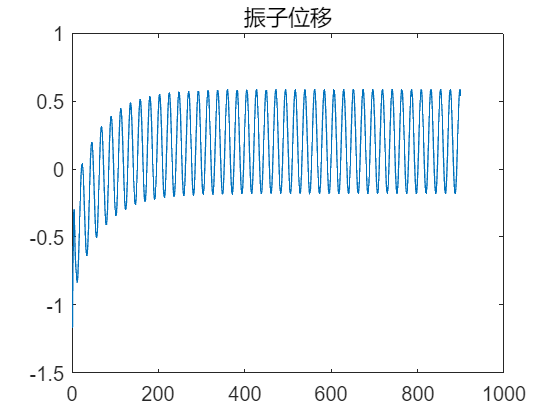

plot(X(2,:))
title('振子位移')
hold off

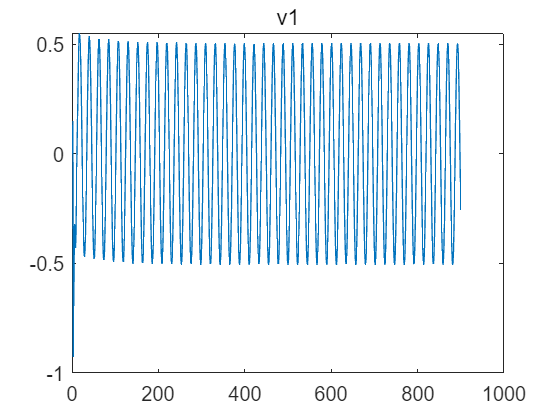

plot(X(3,:))
title('v1')
hold off

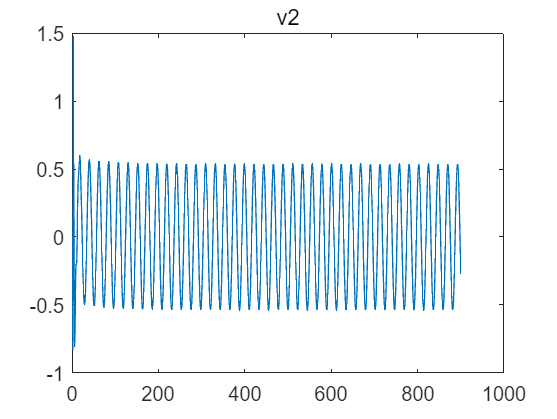

plot(X(4,:))
title('v2')
hold off

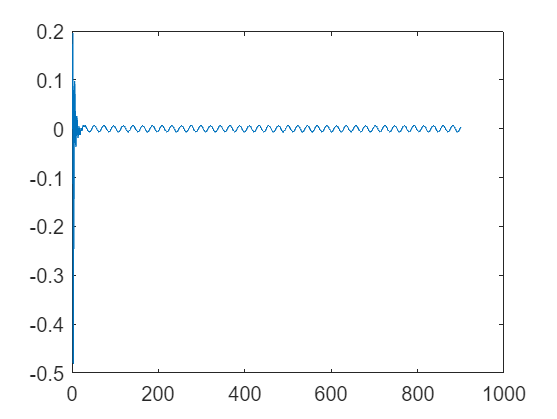

x=X(3,:)*dt-X(4,:)*dt;
plot(x)

dt=0.2;
t=1:ceil(T_end/dt)+2;
t=t*0.2;
t=t';
X=X';
X(:,[2,3])=X(:,[3,2]);




function f=ca_f_float(rho,g,x,L,V0,V_max,r_cost)
    %计算浮力   
    if x>=1
        delta_V=V0-V_max;
    elseif x>0.8-L&&x<1
        delta_V=V0-x*2*pi*r_cost^2; 
    elseif x<(-L+0.8)&&x>-L
        delta_V=V0-1/3*rho*g*(L-0.8+x)^3*(0.8/r_cost)^2*pi;
    else 
        delta_V=0;
    end
    f=rho*g*delta_V;
end
function dxdt=S_diff_equ(X,t,k,flag)
    x1=X(1);
    x2=X(2);
    v1=X(3);
    v2=X(4);
    m1=4866;                    %浮子质量 (kg)
    r_f=1;                      %浮子底半径 (m)
    h_cast=3;                   %浮子圆柱部分高度 (m)
    h_cone=0.8;                 %浮子圆锥部分高度 (m)
    V_cast=pi*r_f^2*h_cast;     %圆柱体积 (m3)
    V_cone=1/3*h_cone*pi*r_f^2; %圆锥体积(m3)
    V_max=V_cone+V_cast;        %浮子体积
    m2=2433;                    %振子质量 (kg)
    m_add=1335.535;             %垂荡附加质量 (kg)
    g=9.8;                      %重力加速度 (m/s2)
    G1=m1*g;                    %浮子重力  (N)
    G2=m2*g;                    %振子重力  (N)
    rho=1025;                   %海水的密度 (kg/m3)
    ke=80000;                   %弹簧刚度 (N/m)
    l0=0.5;                     %弹簧原长 (m)
    w=1.4005;                   %入射波浪频率 (rad/s)orsay %入射波浪角速度（rad/s）                 
    kr=656.3616;                %垂荡兴波阻尼系数 (N·s/m)
    f_max=6250;                 %垂荡激励力振幅 (N)
    l=l0-m2*g/ke;               %弹簧的初始压缩量
    V0=(m1+m2)/rho;             %初始沉入水中体积(m3)
    L=2.3-2/15;                 %重心距底端距离
    r_cost=1;                   %浮子底半径 (m)
    if flag 
        k=10000*(abs(v1-v2))^(1/2);
    end
    dxdt=[v1;
        v2;
        (-k*(v1-v2)-ke*(x1-x2+l)-f_max*cos(w*t)-kr*v1-ca_f_float(rho,g,x1,L,V0,V_max,r_cost))/(m1+m_add);
        (k*(v1-v2)+ke*(x1-x2+l))/m2];
    
end